## Project tasks -1

### Sentences for pro 1: ‘C_01_01.wav’ & ‘C_01_02.wav’ 

Frequency-to-place mapping in cochlea:


$$f=165\ldotp 4\times \left({10}^{0\ldotp 06\cdot d} -1\right)$$


where $f$ is -3 dB cut-off frequency, and $d$ is the distance (in millimeter) along the cochlea.

读取音频，生成SSN

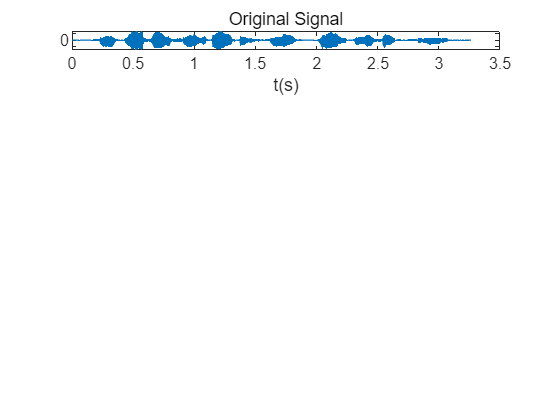

[x1,~]=audioread('.\resource\C_01_01.wav');
[x2,fs]=audioread('.\resource\C_01_02.wav');
x1=x1';
x2=x2';

fcut=50;
figure
subplot(5,1,1),plot(xTime(x1,fs),x1),title('Original Signal'),xlabel('t(s)')

SSN=createSSN(x1,fs);

### Task 1 

#### • Set LPF cut-off frequency to 50 Hz. 将低通滤波截止频率设置为50Hz。

#### • Implement tone-vocoder by changing the number of bands to N=1, N=2, N=4, N=6, and N=8.

#### • Save the wave files for these conditions, and describe how the number of bands affects the intelligibility (i.e., how many words can be understood) of synthesized sentence.

n1=4;n2=4;
y1=voiceSynthesize(x1,1,n1,n2,50,fs);
%信号x1，N=1,带通4阶，低通4阶，fcut=50，采样频率fs
y2=voiceSynthesize(x1,2,n1,n2,50,fs);
y4=voiceSynthesize(x1,4,n1,n2,50,fs);
y6=voiceSynthesize(x1,6,n1,n2,50,fs);
y8=voiceSynthesize(x1,8,n1,n2,50,fs);

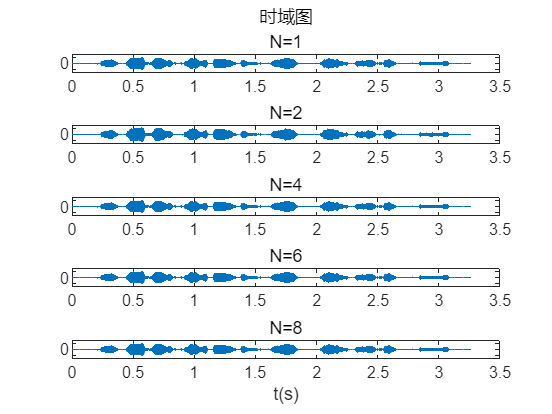

plotTimeGraph(y1,fs,5,1,'N=1')
plotTimeGraph(y2,fs,5,2,'N=2')
plotTimeGraph(y1,fs,5,3,'N=4')
plotTimeGraph(y1,fs,5,4,'N=6')
plotTimeGraph(y1,fs,5,5,'N=8')

**Different methods for evaluation**

谱图（Spectrogram）

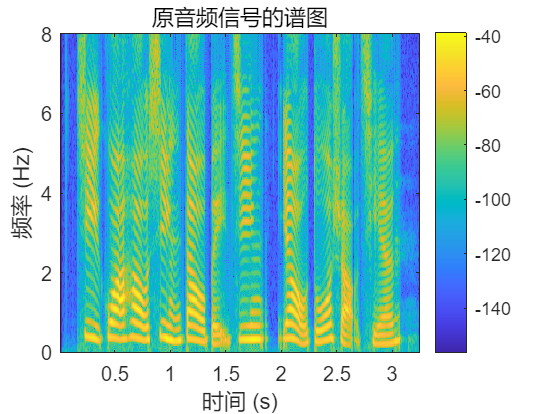

plotSpectrogram(x1,fs,"原音频信号的谱图")

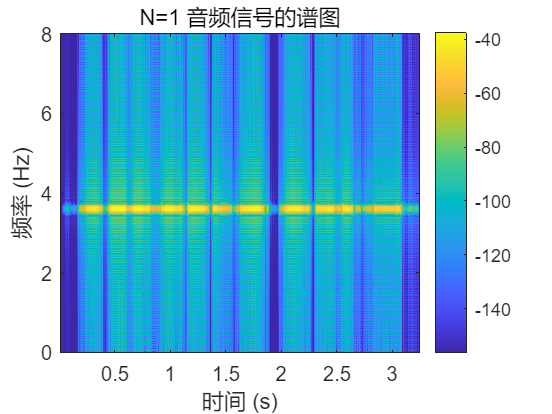

plotSpectrogram(y1,fs,"N=1 音频信号的谱图")

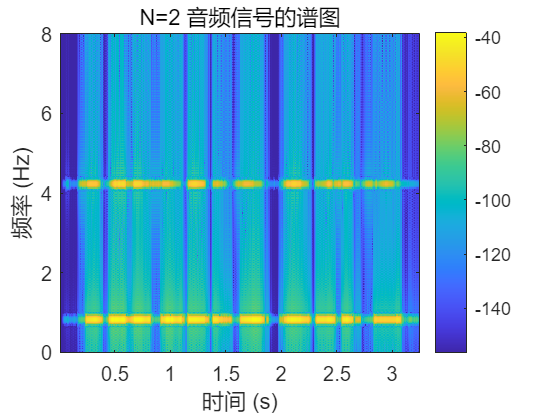

plotSpectrogram(y2,fs,"N=2 音频信号的谱图")

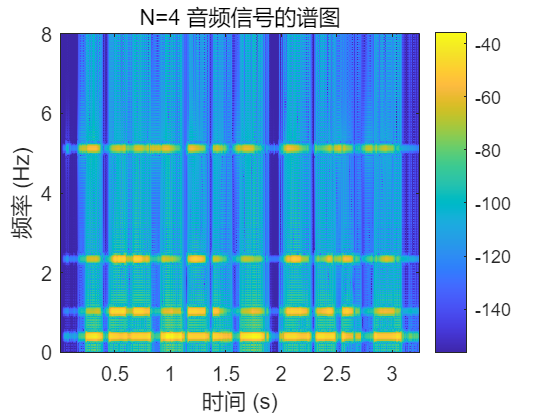

plotSpectrogram(y4,fs,"N=4 音频信号的谱图")

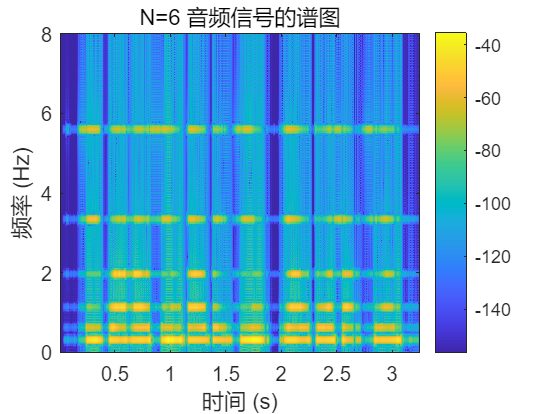

plotSpectrogram(y6,fs,"N=6 音频信号的谱图")

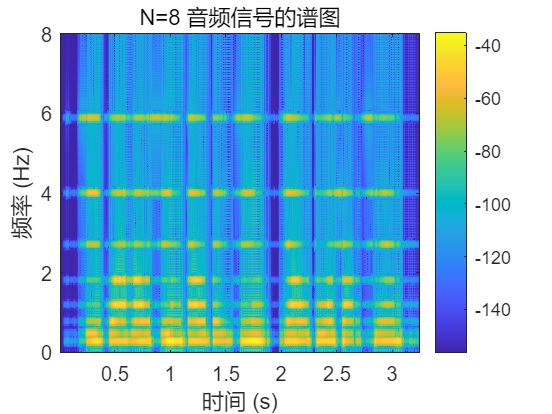

plotSpectrogram(y8,fs,"N=8 音频信号的谱图")

共振峰图

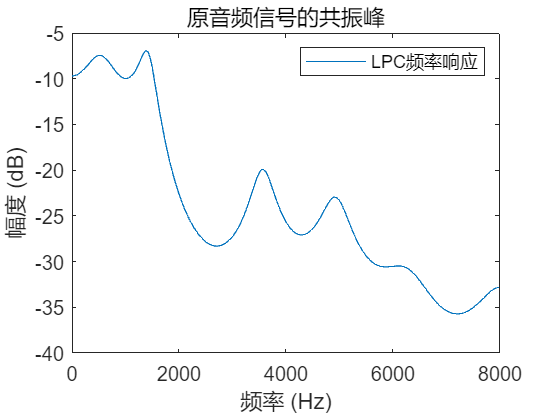

plotResonHump(x1,fs,"原音频信号的共振峰")

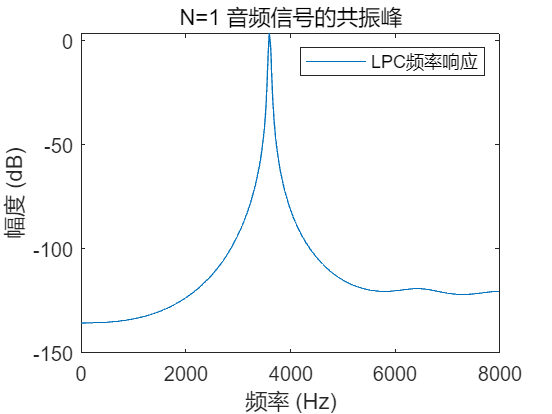

plotResonHump(y1,fs,"N=1 音频信号的共振峰")

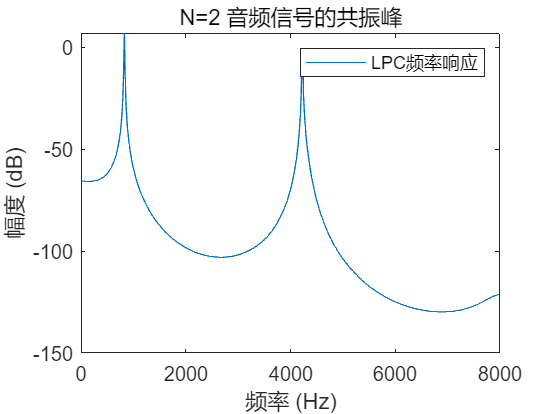

plotResonHump(y2,fs,"N=2 音频信号的共振峰")

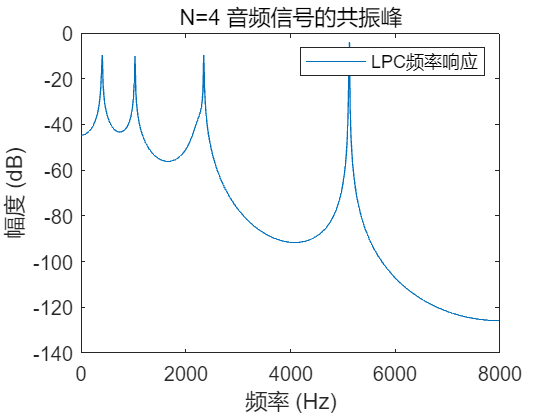

plotResonHump(y4,fs,"N=4 音频信号的共振峰")

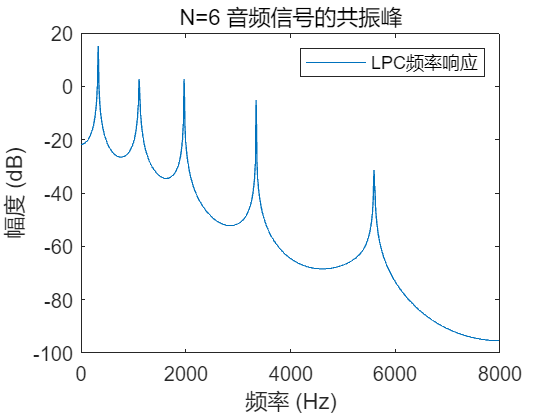

plotResonHump(y6,fs,"N=6 音频信号的共振峰")

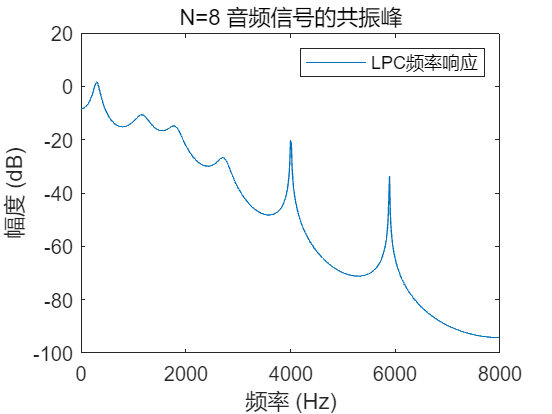

plotResonHump(y8,fs,"N=8 音频信号的共振峰")

### **Task2**

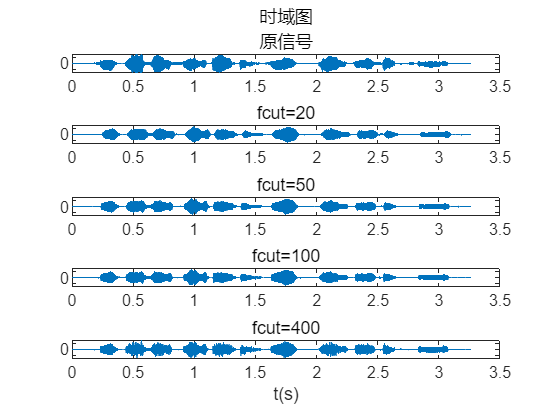

%set the number of bands to N=4
yfs20=voiceSynthesize(x1,4,n1,n2,20,fs);
yfs50=voiceSynthesize(x1,4,n1,n2,50,fs);
yfs100=voiceSynthesize(x1,4,n1,n2,100,fs);
yfs400=voiceSynthesize(x1,4,n1,n2,400,fs);

plotTimeGraph(x1,fs,5,1,'原信号')
plotTimeGraph(yfs20,fs,5,2,'fcut=20')
plotTimeGraph(yfs50,fs,5,3,'fcut=50')
plotTimeGraph(yfs100,fs,5,4,'fcut=100')
plotTimeGraph(yfs400,fs,5,5,'fcut=400')

### **Task3**

SNR=-5

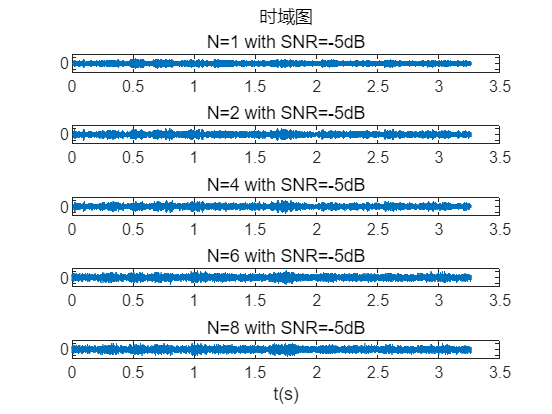

yn=noisySig(x1,SSN,-5);

y1n=voiceSynthesize(yn,2,n1,n2,50,fs);
y2n=voiceSynthesize(yn,4,n1,n2,50,fs);
y3n=voiceSynthesize(yn,6,n1,n2,50,fs);
y4n=voiceSynthesize(yn,8,n1,n2,50,fs);
y5n=voiceSynthesize(yn,16,n1,n2,50,fs);

plotTimeGraph(y1n,fs,5,1,'N=1 with SNR=-5dB')
plotTimeGraph(y2n,fs,5,2,'N=2 with SNR=-5dB')
plotTimeGraph(y4n,fs,5,3,'N=4 with SNR=-5dB')
plotTimeGraph(y6n,fs,5,4,'N=6 with SNR=-5dB')
plotTimeGraph(y8n,fs,5,5,'N=8 with SNR=-5dB')

### Task4

Set N=6

yn20=voiceSynthesize(yn,6,n1,n2,20,fs);
yn50=voiceSynthesize(yn,6,n1,n2,50,fs);
yn100=voiceSynthesize(yn,6,n1,n2,100,fs);
yn400=voiceSynthesize(yn,6,n1,n2,400,fs);


function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function SSN=createSSN(x,fs)%上节课做的生成SSN
    x=x';
    sig=repmat(x,1,10);
    nfft=512;
    [Pxx,w]=pwelch(sig,hamming(nfft),nfft/2,nfft,fs);
    b=fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx)));
    white_noise=1-2*rand(1,length(x)+3000);
    SSN=filter(b,1,white_noise);
    SSN=SSN(2000:end);
    %Discard the beginning which has little sound.
    SSN=SSN(1:length(x));
end

function [Fs,fmid]=createBandDivision(N)

    %输入想要获得多少个带
    %Fs是每个带的频率区间，每个元素都是二元素向量
    %fmid是每个区间的中间频率，用于以后乘sinewave
    fmin=200;
    fmax=7000;
    dmin=log10(fmin/165.4+1)/0.06;
    dmax=log10(fmax/165.4+1)/0.06;
    D=linspace(dmin,dmax,N+1);
    F=zeros(1,N+1);
    for k=1:N+1
        F(k)=165.4*(10^(0.06*D(k))-1);
    end
    Fs=zeros(N,2);
    fmid=zeros(N,1);
    for k=1:N
        Fs(k,:)=[F(k),F(k+1)];
        fmid(k)=(F(k)+F(k+1))/2;
    end
end

function y=voiceSynthesize(x,N,n1,n2,fcut,fs)
    %输入音频x，切割带数N，n1带通滤波阶数，n2低通滤波阶数
    [Fs,fmid]=createBandDivision(N);
    y=zeros(1,length(x));
    %初始化信号长度，否则后面无法相加
    for k=1:N
        [b,a]=butter(n1,Fs(k,:)/(fs/2),"bandpass");
        
        y_filtered=filter(b,a,x);

        [b,a]=butter(n2,fcut/(fs/2),'low');
        %低通滤波取得包络，阶数为4
        y_env=filter(b,a,abs(y_filtered));

        sin_mid=sin(2*pi*fmid(k).*(xTime(x,fs)));
        y_mod=sin_mid.*y_env;
        y=y+y_mod;
        y=y./norm(y).*norm(x);
    end
end

function y=noisySig(x,SSN,dB)
    y=x+SSN./norm(SSN).*norm(x)*10^(-dB/20);
    y=y./norm(y).*norm(x);
end

function plotSpectrogram(x,fs,Title)
    %信号x，采样率fs，标题（用''包裹的String）
    window = hamming(256); % 窗函数
    noverlap = 128; % 重叠样本数
    nfft = 512; % FFT点数
    figure
    spectrogram(x, window, noverlap, nfft, fs, 'yaxis')
    title(Title);
    colorbar;
    xlabel('时间 (s)');
    ylabel('频率 (Hz)');
end

function plotTimeGraph(x,fs,a,n,Title)
    %subplot(a,1,n)
    if n==1
        figure
    end
    subplot(a,1,n),plot(xTime(x,fs),x),subtitle(Title),ylim([-0.3,0.3])
    if n==1
        title('时域图')
    end
    if n==a
        xlabel('t(s)')
        %只在最下面标出横轴坐标，节约空间
    end
end

function plotResonHump(x,fs,Title)
    %resonance hump: 共振峰
    %参数同plotSpectrogram()
    x=x/max(abs(x));%归一化信号
    order=12;% LPC 阶数，可以根据需要调整
    [a,g]=lpc(x,order);
    [h,w]=freqz(sqrt(g),a,512,fs);
    figure
    plot(w,20*log10(abs(h)));
    xlabel('频率 (Hz)');
    ylabel('幅度 (dB)');
    title(Title);
    legend("LPC频率响应")
end